clc, clear

%% Load Data

% PF205_20180101
% This subject has corrupted egg signals
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_soft_a.mat";
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_soft_a-2.mat";
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_loud_a.mat";

% PF217_20180101
%matFile = "E:\code\fulldata\P50\PF217\W1\InLab\MAT calibrated segments\PF217_20180101_soft_a.mat"; % <- A lot of noise in this signal
%matFile = "E:\code\fulldata\P50\PF217\W1\InLab\MAT calibrated segments\PF217_20180101_loud_a";

% NM145_20141231
% noise at 0.8 kHz 
%matFile = "E:\code\fulldata\R33\NM145\W1\InLab\MAT calibrated segments\NM145_20141231_soft_a.mat";
%matFile = "E:\code\fulldata\R33\NM145\W1\InLab\MAT calibrated segments\NM145_20141231_loud_a.mat";

% PF235_20180101
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_loud_a.mat";
% This signal has noise
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_soft_a.mat"; 
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_speech.mat";

% NF217_20221231
%matFile = "E:\code\fulldata\P50\NF217\W1\InLab\MAT calibrated segments\NF217_20221231_loud_a.mat";
matFile = "E:\code\fulldata\P50\NF217\W1\InLab\MAT calibrated segments\NF217_20221231_soft_a.mat";

load(matFile)
mic = Mic.Data;
sound = false;
if sound
    soundsc(mic, fs);
end
egg = EGG.Data;

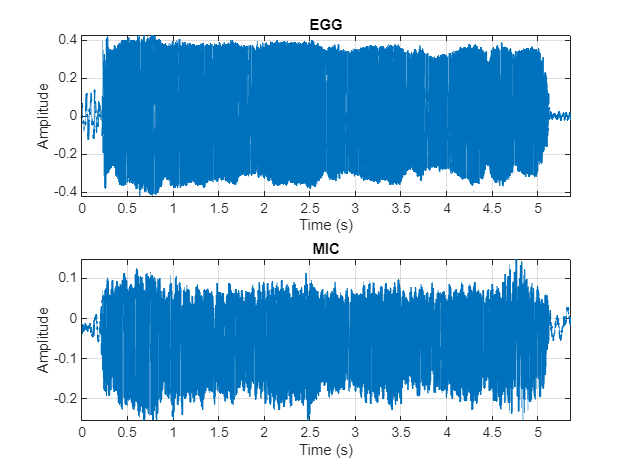

t = (0:length(EGG.Data)-1) / fs;

show_full = true;  
t_init = 0.2; t_end = 0.35; % Ax limits
plotSignals(egg, "EGG", mic, "MIC", fs, show_full, t_init, t_end)

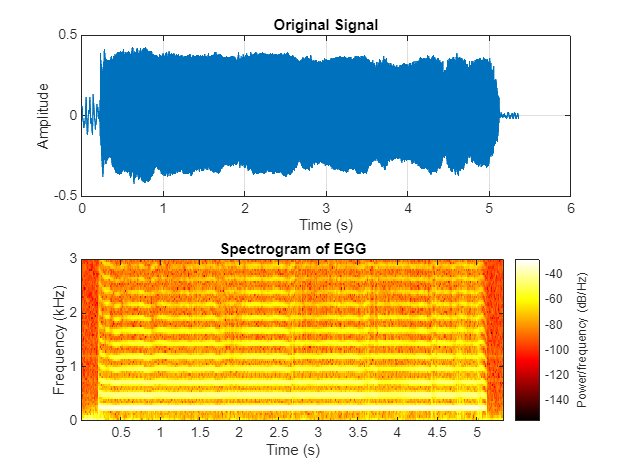

plotSpectrogram(egg, fs)
subplot(2,1,2)
ylim([0 3])

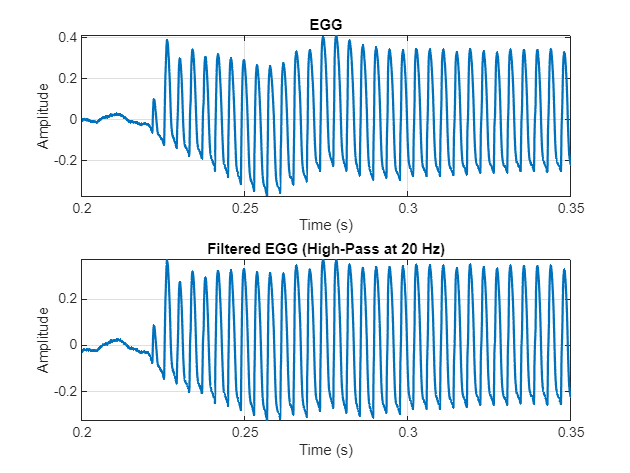

% Functions to pre-process
function [y,b] = zeroDelayFIR(x, Fs)
N = 1024;
b = fir1(N, 20/(Fs/2), 'high');
y = filtfilt(b, 1, x);
end
%detrendegg = detrend(egg,6);
% High pass at 20 Hz, differentiate with gradient
[fegg, b] = zeroDelayFIR(egg,fs);     

%figure;
%freqz(b, 1, 2048, fs);  

show_full = false;
plotSignals(egg, "EGG", fegg, "Filtered EGG (High-Pass at 20 Hz)", fs, show_full, t_init, t_end)

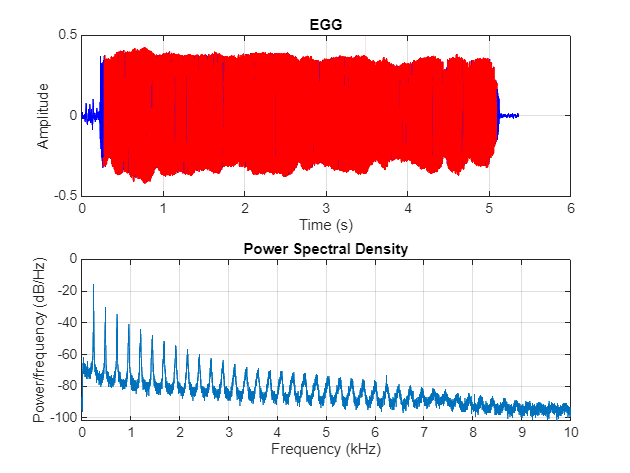

% Ignore the transitions at the beginning and end of the signal to get the
% pwelch. use only the sustained portion 
startPercentage = 0.05;
endPercentage = 0.95;
plotPwelch(fegg,"EGG",fs, startPercentage, endPercentage)

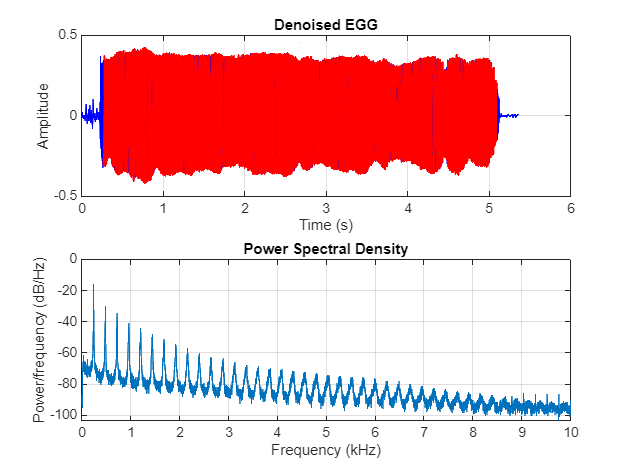

% Denoise signal with wavelets
eggDEN = wdenoise(fegg);
plotPwelch(eggDEN,"Denoised EGG", fs, startPercentage, endPercentage)

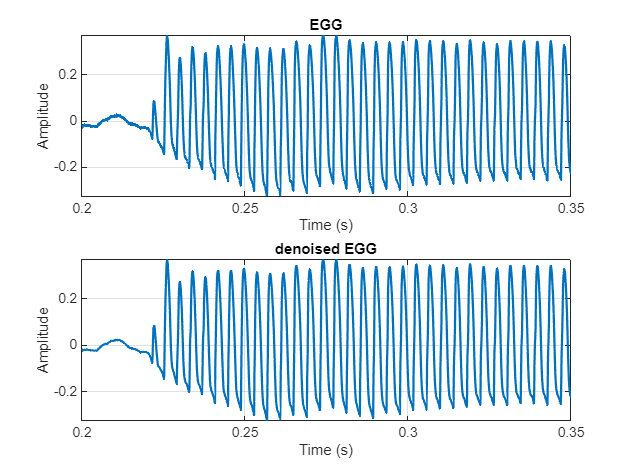

% Plot EGG signal and denoised signal
show_full = false;
plotSignals(fegg, "EGG", eggDEN, "denoised EGG", fs, show_full, t_init, t_end)

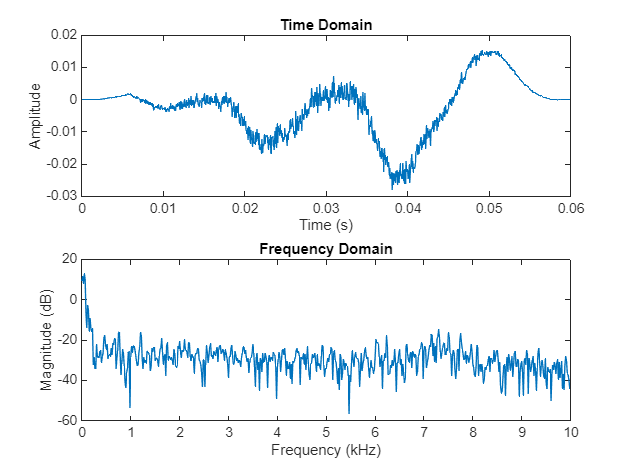

% Inspect the noise at the beggining of the EGG signal for the original
% filtered signal and the denoised signal
use_time = false;

if use_time
    t_init = 2.95; t_end = 3.25;
    start_idx = round(t_init * fs); end_idx = round(t_end * fs);
else
    start_idx = 1;
    end_idx = round(0.06 * fs);
end

segment = fegg(start_idx:end_idx);
w = hann(length(segment));
segment_windowed = segment(:) .* w;

segmentDEN = eggDEN(start_idx:end_idx);
segmentDEN_windowed = segmentDEN(:) .* w;

plotFFT(segment_windowed, fs);

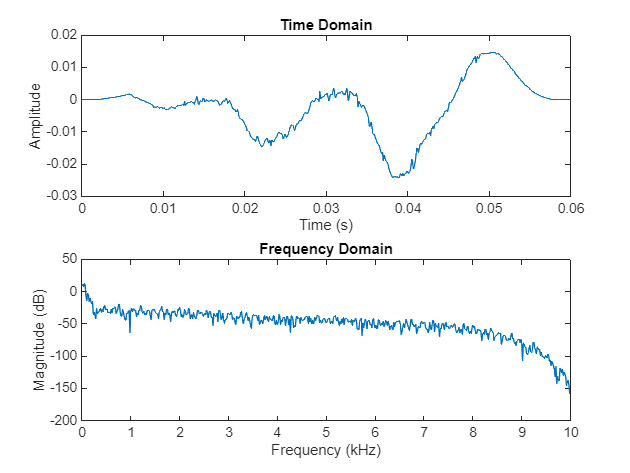

plotFFT(segmentDEN_windowed, fs);

At this point, we have eggDEN, which is the signal denoised using wavelets and subsequently high-pass filtered at 20 Hz

N = length(eggDEN);
startIdx = floor(0.1 * N) + 1;
endIdx = floor(0.9 * N);
eggDEN = eggDEN(startIdx:endIdx);
t = (0:length(eggDEN)-1) / fs;

Differentiate the signal using the gradient <- Increase the signal noise

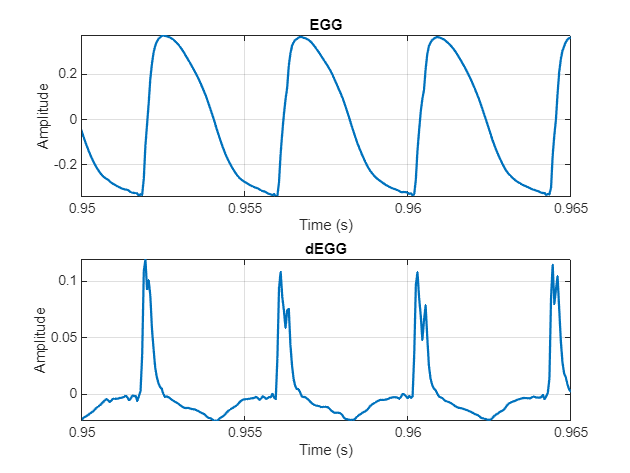

degg1 = gradient(eggDEN);
show_full = false;  
t_init = 0.95; t_end = 0.965; 
plotSignals(eggDEN, "EGG", degg1, "dEGG", fs, show_full, t_init, t_end)

1. Discrete time differentiator as bandpass, this can affect the shape of the signal

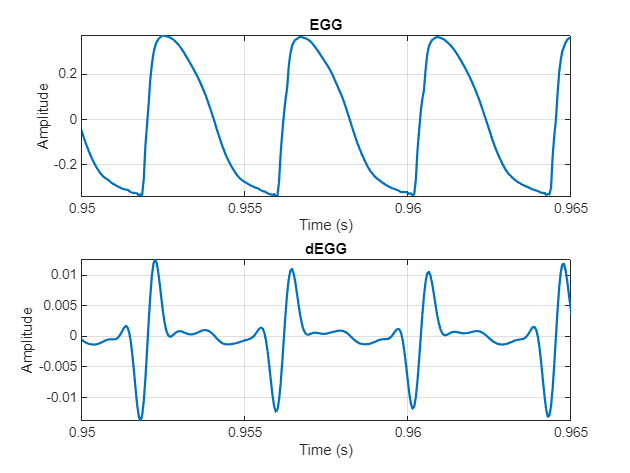

function [y, b] = zeroDelayDiffFIR(x, Fs)
Nf = 50;
Fpass = 20;
Fstop = 4000;
d = designfilt('differentiatorfir','FilterOrder',Nf, ...
    'PassbandFrequency',Fpass,'StopbandFrequency',Fstop, ...
    'SampleRate',Fs);
b = d.Coefficients;
y = filtfilt(b, 1, x);
end
[degg2, b] = zeroDelayDiffFIR(eggDEN,fs);
%figure;
%freqz(b, 1, 2048, fs);  

% Plot EGG and dEGG after filtering
plotSignals(eggDEN, "EGG", degg2, "dEGG", fs, show_full, t_init, t_end)

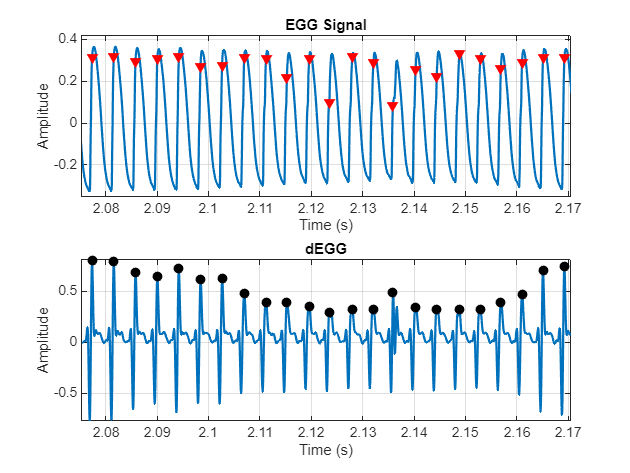

% Find peaks of the degg signal

%{
degg2 = 2 * ((degg2 - min(degg2)) / (max(degg2) - min(degg2))) - 1;
%degg2 = max(degg2, 0);
threshold = mean(degg2) + 1*std(degg2);  % o 3*std si el ruido es fuerte
threshold = 0.3 * max(degg2);
%[pks,locs] = findpeaks(degg2, 'MinPeakProminence', 0.5); 
[pks,locs] = findpeaks(degg2, 'MinPeakHeight', threshold); 
%}

degg2 = 2*((degg2 - min(degg2))./(max(degg2)-min(degg2))) - 1;
threshold   = 0.25*max(degg2);
[pks,locs]  = findpeaks(degg2,'MinPeakHeight',threshold);

% Estimar periodo y segunda pasada
T  = round(median(diff(locs)));              % periodo en muestras
[pks,locs] = findpeaks(degg2, ...
                       'MinPeakHeight',threshold, ...
                       'MinPeakDistance',floor(0.8*T));

show_full = true;  
t_init = 0.10; t_end = 0.25; % Ax limits

figure;
ax1 =subplot(2,1,1);
plot(t, eggDEN, 'LineWidth', 1.5);
hold on;
plot(t(locs), eggDEN(locs), 'rv', 'MarkerFaceColor', 'r');  % Mark corresponding EGG values at dEGG peaks
xlabel('Time (s)');
ylabel('Amplitude');
title('EGG Signal');
grid on;
axis tight;
if ~show_full
    xlim([t_init, t_end]);
end

ax2 = subplot(2,1,2);
plot(t, degg2, 'LineWidth', 1.5);
hold on;
plot(t(locs), pks, 'ko', 'MarkerFaceColor', 'k');  % Mark dEGG peaks
xlabel('Time (s)');
ylabel('Amplitude');
title('dEGG');
grid on;
axis tight;
if ~show_full
    xlim([t_init, t_end]);
end
linkaxes([ax1, ax2], 'x');